%% Recolección de datos

clear
simul=sim('PenduloForzadoKalman'); 
t = simul.t;
Ts=t(2)-t(1);

x = simul.x; % Se mide la posición de la primera masa (x1 = xa)

u = simul.u;
N = length(t); 
yteo =[simul.y] ; 
y_names ='y';

%% Inicialización de las matrices
x0 = [0; 0; 1.2];
P0 = 0.01*eye(3); 
Q = 0.01*eye(3); 
Av=1;
R=Av^2;


x_act = zeros(3,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1); 
de_x = zeros(3,N); 
N_cond = zeros(N,1);
de_x1 = zeros(N,1); 
de_x2= zeros(N,1); 
de_x3 = zeros(N,1);
x_pre = x0; 
P_pre = P0; 
C= [1 0 0];
%C=[0 1 0]; Salen NaN con este (Significa que no es observable)
% Valores estimados anteriormente (Practica 2 Alg. Gene.)
Delta=0.3413;
Alpha = 1.2045;
Beta = 2.1936;

%Error del 20%

for i=1:N
    % Corrección del estado
    K=P_pre*C'/(C*P_pre*C' + R); 
    x_act(:,i)= x_pre + K*( x(i) - x_pre(1) );
    P_act = ( eye(3) - K*C )*P_pre;
    P_act = (P_act + P_act')/2; % Simetrizacion de la matriz P ****
    % Actualización del estado
    A=[0 1 0; 
      (-x_act(3,i)-3*Beta*(x_act(1,i)^2)) -Delta (-x_act(1,i)); 
      0 0 1]; %Linealización Matriz A
    Fi=eye(3) + Ts*A;
    x_pre=[x_act(1,i) + Ts*x_act(2,i);
           x_act(2,i) + Ts*(u(i) - Delta*(x_act(2,i)) - x_act(3,i)*x_act(1,i) - Beta*(x_act(1,i))^3); 
           x_act(3,i)]; % Discretización de Euler
    P_pre = Fi*P_act*Fi' + Q; 
    P_act_traza(i) = trace(P_act); 
    K_norma(i) = norm(K);
    N_cond(i)=cond(obsv(Fi,C));
    
    de_x1(i) = sqrt(P_act(1,1)); de_x2(i) = sqrt(P_act(2,2)); de_x3(i) = sqrt(P_act(3,3));
    
end
rank(obsv(Fi,C))

ans = 3

e_est = x - x_act(1,:)'; % Residuos
de_x1 = sqrt(P_act(1,1)); 
de_x2 = sqrt(P_act(2,2)); 
de_x3 = sqrt(P_act(3,3));

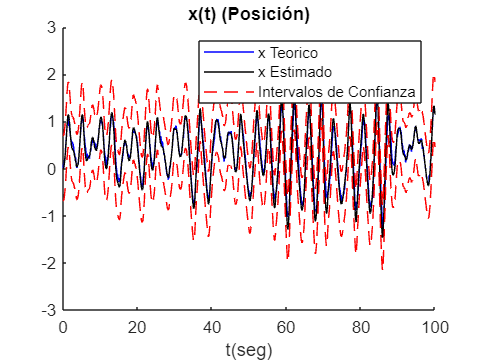


% Grafica para Estado conocido X (Posición)
figure
hold on
plot (t,x(:,1),'b')
plot(t,x_act(1,:)','k')
plot(t,x_act(1,:)+de_x1,'r--')
plot (t,x_act(1,:)'-de_x1,'r--')
xlabel('t(seg)')
title('x(t) (Posición)')
legend({'x Teorico' 'x Estimado' 'Intervalos de Confianza'})

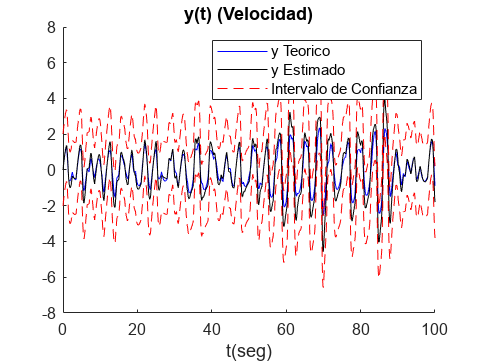


% Grafica para Estado estimado Y (Velocidad)
figure
hold on
plot(t,yteo,'b') % 'y Teorico'
plot (t, x_act(2,:)','K')
plot(t,x_act(2,:)'+de_x2,'r--')
plot (t,x_act(2,:)'-de_x2,'r--')
xlabel('t(seg)')
title('y(t) (Velocidad)')
legend({'y Teorico' 'y Estimado' 'Intervalo de Confianza'})

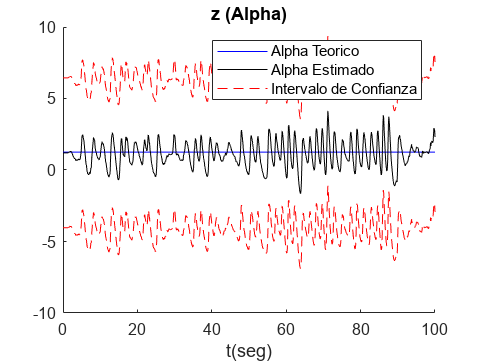


% Grafica para Estado (Parametro) estimado Z (Alpha)
figure
hold on
plot(t,Alpha*ones(N,1),'b') % 'Alpha Teorico'
plot(t,x_act(3,:)','K')
plot (t,(x_act(3,:) + de_x3)','r--')
plot(t,(x_act(3,:) - de_x3)','r--')
xlabel('t(seg)')
title('z (Alpha)')
legend({'Alpha Teorico' 'Alpha Estimado' 'Intervalo de Confianza'})

## Ganancia de Kalman y matriz de covarianzas de los errores de los estados estimados

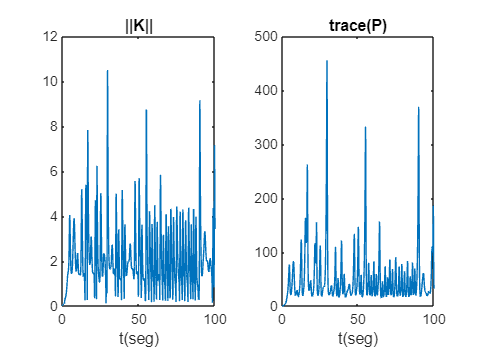

figure

tiledlayout(1,2)

nexttile, plot(t,K_norma), xlabel('t(seg)'), title('||K||')

nexttile, plot(t,P_act_traza), xlabel('t(seg)'), title('trace(P)')

## Test de Blancura

figure
whiteness_test(e_est)

## N_Condición

figure
plot(t,N_cond')
title('Numero Condición')